Constantes utilizadas en el estudio

Fmax = 0.826103977267828;
Isp = 0.007983105820217;
g0 = 3.598141767655429e+03;
m_s = 328900;
ro_s = 3.887800000000000e+02;
mu = 0.012150664267000;
w_0 = 0;
w_s = -0.925179999954674;
m_0 = 1;
R_e = 1.658E-2;
d_v_0 = 3.032757;
H_0 = 4.3418E-4;
H_f = 48303;
R_f = 5000;

Ejecución del sistema sin coestados

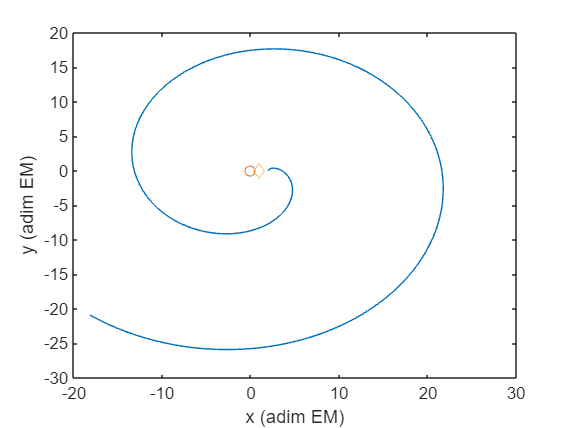

Tf=10;
options=odeset('RelTol',1e-8,'AbsTol',1e-8);
tspan=0:.01:Tf;
parametros = [Isp g0 Fmax ro_s mu w_0 w_s m_s 0 0];
ci = [2 0 0 1 1];
[t,estados_sc]=ode45(@(t,st)motor_bicircular_sin_coestados(t,st,parametros),tspan,ci,options);
plot(estados_sc(:,1),estados_sc(:,2));
hold on
plot(-mu, 0, 'o')
hold on
plot(1-mu, 0, 'd')
hold off
xlabel("x (adim EM)")
ylabel("y (adim EM)")

estados_sc

estados_sc =    2.000000000000000                   0                   0   1.000000000000000   1.000000000000000
   2.000188332089318   0.009998882802911   0.037665712250247   0.999664831999840   1.000000000000000
   2.000753286006779   0.019991062478128   0.075322953799674   0.998659397955796   1.000000000000000
   2.001694734688137   0.029969837191095   0.112963251778800   0.996983907594636   1.000000000000000
   2.003012466278259   0.039928508887983   0.150578130193707   0.994638710073925   1.000000000000000
   2.004706184208293   0.049860382332855   0.188159107298683   0.991624293941622   1.000000000000000
   2.006775507091298   0.059758766889701   0.225697692725352   0.987941285986111   1.000000000000000
   2.009219968488460   0.069616980809254   0.263185387263814   0.983590449989637   1.000000000000000
   2.012039016904997   0.079428351306913   0.300613682863824   0.978572686708052   1.000000000000000
   2.015232015758276   0.089186215161147   0.337974060917734   0.9728890327016

Ejecución del sistema con coestados

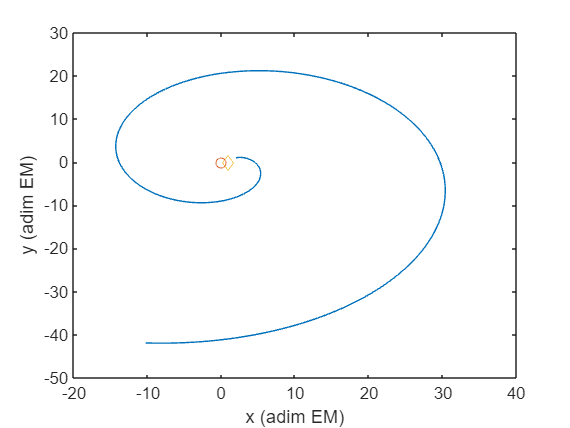

Tf=10;
options=odeset('RelTol',1e-8,'AbsTol',1e-8);
tspan=0:.01:Tf;
parametros = [Isp g0 Fmax ro_s mu w_0 w_s m_s];
ci = [2 1 3 1 1 2 1 3 5 2];
[t,estados]=ode45(@(t,st)motor_bicircular(t,st,parametros),tspan,ci,options);
plot(estados(:,1),estados(:,2));
hold on
plot(-mu, 0, 'o')
hold on
plot(1-mu, 0, 'd')
hold off
xlabel("x (adim EM)")
ylabel("y (adim EM)")

estados

estados =     2.0000    1.0000    3.0000    1.0000    1.0000    2.0000    1.0000    3.0000    5.0000    2.0000
    2.0302    1.0097    3.0337    0.9417    0.9997    1.9602    0.9490    3.0795    4.9295    1.9519
    2.0607    1.0188    3.0665    0.8829    0.9994    1.9199    0.8987    3.1580    4.8578    1.9039
    2.0915    1.0274    3.0983    0.8237    0.9991    1.8792    0.8491    3.2354    4.7852    1.8561
    2.1226    1.0353    3.1291    0.7641    0.9988    1.8381    0.8003    3.3118    4.7115    1.8083
    2.1541    1.0426    3.1590    0.7040    0.9986    1.7965    0.7523    3.3871    4.6367    1.7607
    2.1858    1.0494    3.1879    0.6435    0.9983    1.7544    0.7050    3.4613    4.5609    1.7132
    2.2178    1.0555    3.2159    0.5826    0.9980    1.7119    0.6585    3.5344    4.4842    1.6658
    2.2501    1.0610    3.2428    0.5214    0.9977    1.6689    0.6128    3.6064    4.4064    1.6184
    2.2827    1.0659    3.2688    0.4598    0.9974    1.6255    0.5679    3.6773 

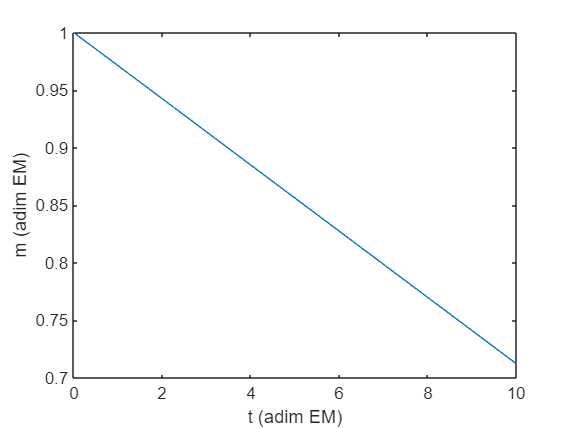

%Gráfico de consumo de combustible
plot(t,estados(:,5))
xlabel("t (adim EM)")
ylabel("m (adim EM)")

Cálculo de las condiciones iniciales

s_0 = 1;
alfa = pi/2;
p_m0 = 1;
gamma_1 = .5;
gamma_2 = .5;
gamma_3 = .5;
Tf=10;

r_0 = R_e + H_0;
[x_0, y_0, v_x_0, v_y_0 , p_x_0, p_y_0, p_vx_0, p_vy_0] = calcular_ci(alfa, mu, s_0, r_0, d_v_0, gamma_1, gamma_2, gamma_3);
ci = [x_0 y_0 v_x_0 v_y_0 m_0 p_x_0 p_y_0 p_vx_0 p_vy_0 p_m0];

options=odeset('RelTol',1e-8,'AbsTol',1e-8);
tspan=0:.01:Tf;
parametros = [Isp g0 Fmax ro_s mu w_0 w_s m_s]

parametros = 1.0e+05 *

   0.000000079831058   0.035981417676554   0.000008261039773   0.003887800000000   0.000000121506643                   0  -0.000009251800000   3.289000000000000


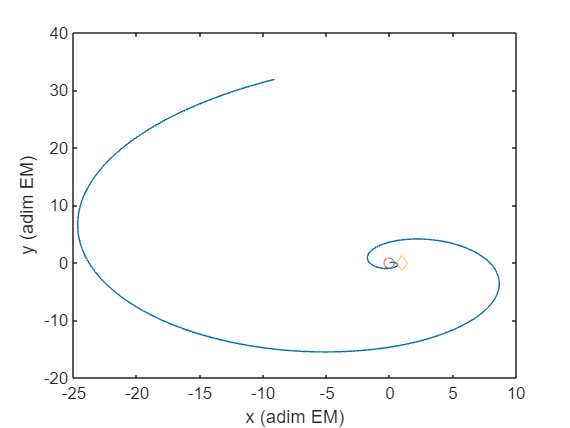

[t,estados]=ode45(@(t,st)motor_bicircular(t,st,parametros),tspan,ci,options);
plot(estados(:,1),estados(:,2));
hold on
plot(-mu, 0, 'o')
hold on
plot(1-mu, 0, 'd')
hold off
xlabel("x (adim EM)")
ylabel("y (adim EM)")

estados

estados = 1.0e+03 *

  -0.000029164844267   0.000000000000000   0.000000000000000   0.010669505774324   0.001000000000000  -0.000500000000000   0.000499999364270   0.000000000000000   0.000500000000000   0.001000000000000
   0.000018355170577   0.000053752834983   0.004851390459017   0.002475159104362   0.000999712402864   0.090256492278102  -0.122696384951058  -0.001185323439000   0.001165050440393   0.000992513530398
   0.000061904982678   0.000070769606754   0.003953642072308   0.001177207756171   0.000999424805729   0.047977890291730  -0.108964246370224  -0.001799394740018   0.002361873178679   0.000973132345047
   0.000098665175151   0.000079618415067   0.003437658222760   0.000649402319800   0.000999137208593   0.032177833739476  -0.095571444553051  -0.002132132202644   0.003420839082522   0.000944055664371
   0.000131205980356   0.000084460182404   0.003089854459486   0.000341164319374   0.000998849611457   0.024036619358604  -0.085617934871456  -0.002331336241900   0.0043692407

ci

ci =   -0.029164844267000   0.000000000000000   0.000000000000001  10.669505774324278   1.000000000000000  -0.500000000000000   0.499999364270125   0.000000000000000   0.500000000000000   1.000000000000000


Definición de la función de disparo

mu = 0.012150664267;

alfa = pi/2;
p_m0 = 1

p_m0 =      1


gamma_1 = .5;
gamma_2 = .5;
gamma_3 = .5;
Tf=10;

parametros = [alfa gamma_1 gamma_2 gamma_3 p_m0 Tf];

[z, estados] = shooting_function(parametros, 1); 

parametros = 1.0e+05 *

   0.000000079831058   0.035981417676554   0.000008261039773   0.003887800000000   0.000000121506643                   0  -0.000009251800000   3.289000000000000


z

z = 1.0e+03 *

   1.117647403465075   0.228189758348302   0.046810287550689  -0.669603807282681  -5.482376250981218  -0.415852629727241


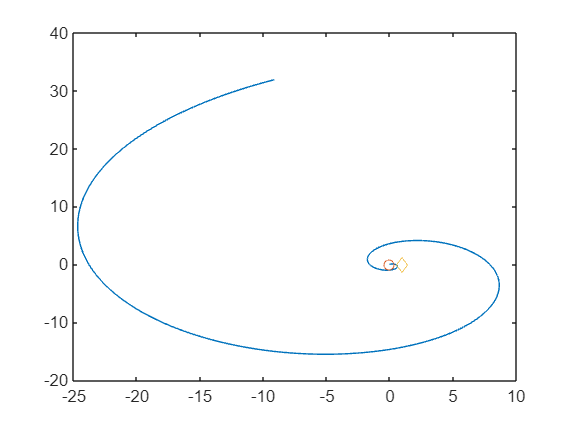

plot(estados(:,1),estados(:,2));
hold on
plot(-mu, 0, 'o')
hold on
plot(1-mu, 0, 'd')
hold off

estados

estados = 1.0e+03 *

  -0.000029164844267   0.000000000000000   0.000000000000000   0.010669505774324   0.001000000000000  -0.000500000000000   0.000499999364270   0.000000000000000   0.000500000000000   0.001000000000000
   0.000018355170577   0.000053752834983   0.004851390459017   0.002475159104362   0.000999712402864   0.090256492278102  -0.122696384951058  -0.001185323439000   0.001165050440393   0.000992513530398
   0.000061904982678   0.000070769606754   0.003953642072308   0.001177207756171   0.000999424805729   0.047977890291730  -0.108964246370224  -0.001799394740018   0.002361873178679   0.000973132345047
   0.000098665175151   0.000079618415067   0.003437658222760   0.000649402319800   0.000999137208593   0.032177833739476  -0.095571444553051  -0.002132132202644   0.003420839082522   0.000944055664371
   0.000131205980356   0.000084460182404   0.003089854459486   0.000341164319374   0.000998849611457   0.024036619358604  -0.085617934871456  -0.002331336241900   0.0043692407

Primera prueba de optimización con matriz 20x20

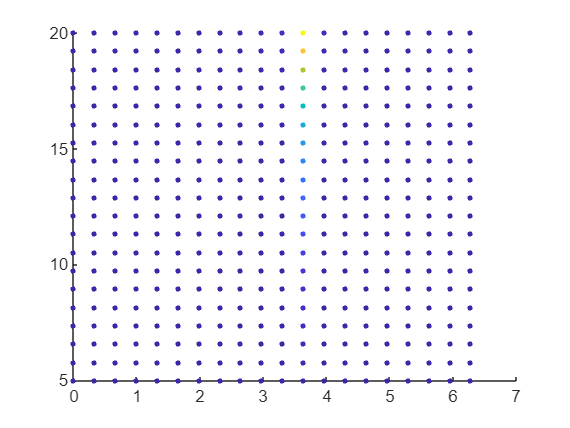

mu = 0.012150664267;

alfa = pi/2; %0-2pi
p_m0 = 1;
gamma_1 = 3;
gamma_2 = 1;
gamma_3 = 0;
Tf=10; %5-20
x_vec = [];
y_vec = [];
n_vec = [];
for alfa = linspace(0,2*pi,20)
    for Tf = linspace(5,20,20)
        parametros = [alfa gamma_1 gamma_2 gamma_3 p_m0 Tf];
        [z, estados] = shooting_function(parametros, 1); 
        n = norm(z);
        x_vec(end+1) = alfa; 
        y_vec(end+1) = Tf;
        n_vec(end+1) = n;
    end
end
scatter(x_vec, y_vec,10,n_vec, 'filled');

[mm inmm]=min(n_vec)


Segunda prueba de optimización con matriz 40x40

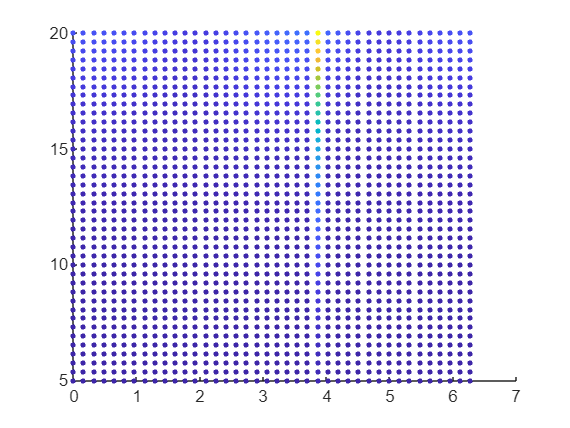

mu = 0.012150664267;

alfa = pi/2; %0-2pi
p_m0 = 1;
gamma_1 = -.5;
gamma_2 = .01;
gamma_3 = -.01;
Tf=10; %5-20
x_vec = [];
y_vec = [];
n_vec = [];
for alfa = linspace(0,2*pi,40)
    for Tf = linspace(5,20,40)
        parametros = [alfa gamma_1 gamma_2 gamma_3 p_m0 Tf];
        [z, estados] = shooting_function(parametros, 1); 
        n = norm(z);
        x_vec(end+1) = alfa; 
        y_vec(end+1) = Tf;
        n_vec(end+1) = n;
    end
end
scatter(x_vec, y_vec,10,n_vec, 'filled');

[mm inmm]=min(n_vec)

mm =   30.714408350424730


inmm =    361


x_vec(inmm)

ans =    1.449965840118366


y_vec(inmm)

ans =      5


Scatterplot de los resultados obtenidos

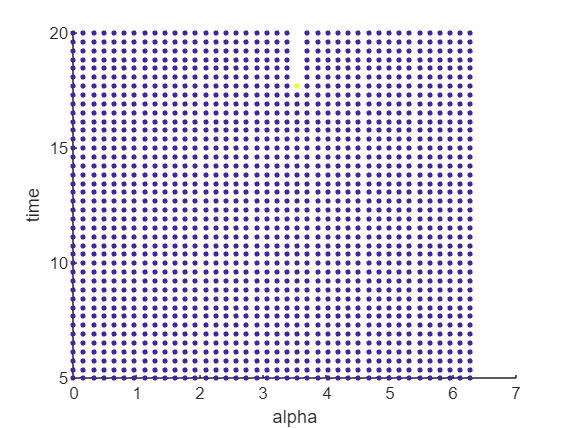

scatter(x_vec, y_vec,10,n_vec, 'filled');
xlabel ("alpha")
ylabel ("time")

Optimización de los parámetros gamma

mu = 0.012150664267;

alfa = 1.44996584011836;
p_m0 = 1;
gamma_1 = .01;
gamma_2 = .01;
gamma_3 = -.01;
Tf=4.5;
parametros = [alfa gamma_1 gamma_2 gamma_3 p_m0 Tf];
[z, estados, t] = shooting_function(parametros, 1); 
z

z =    -0.0148   -0.0504    1.1463   27.6278  -20.9556    0.1038


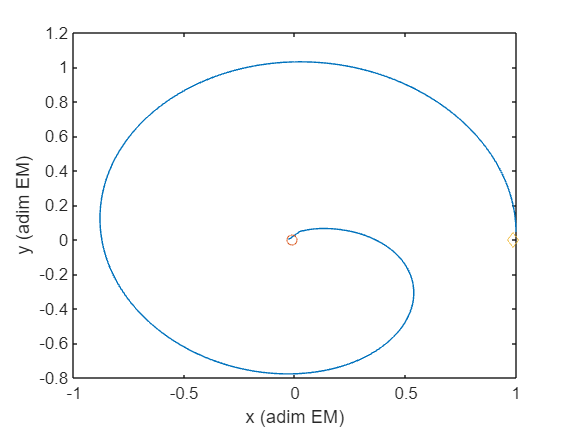

plot(estados(:,1),estados(:,2));
hold on
plot(-mu, 0, 'o')
hold on
plot(1-mu, 0, 'd')
hold off
xlabel("x (adim EM)")
ylabel("y (adim EM)")

estados

estados =    -0.0290    0.0021    1.2848   10.5809    1.0000   -0.0111   -0.0087    0.0012    0.0099    1.0000
    0.0246    0.0495    5.1100    1.8439    0.9997    1.4793   -2.7145   -0.0207    0.0264    0.9998
    0.0698    0.0608    4.0522    0.6601    0.9994    0.6488   -2.3403   -0.0297    0.0523    0.9995
    0.1072    0.0649    3.4691    0.1978    0.9991    0.3533   -2.0328   -0.0332    0.0747    0.9989
    0.1398    0.0654    3.0810   -0.0659    0.9988    0.2056   -1.8119   -0.0343    0.0945    0.9981
    0.1691    0.0638    2.7935   -0.2446    0.9986    0.1188   -1.6445   -0.0338    0.1125    0.9972
    0.1959    0.0607    2.5660   -0.3780    0.9983    0.0631   -1.5116   -0.0323    0.1289    0.9962
    0.2206    0.0563    2.3778   -0.4840    0.9980    0.0253   -1.4024   -0.0300    0.1441    0.9950
    0.2435    0.0510    2.2170   -0.5716    0.9977   -0.0010   -1.3103   -0.0270    0.1582    0.9937
    0.2650    0.0450    2.0761   -0.6462    0.9974   -0.0197   -1.2309   -0.0236 

Consumo final de combustible

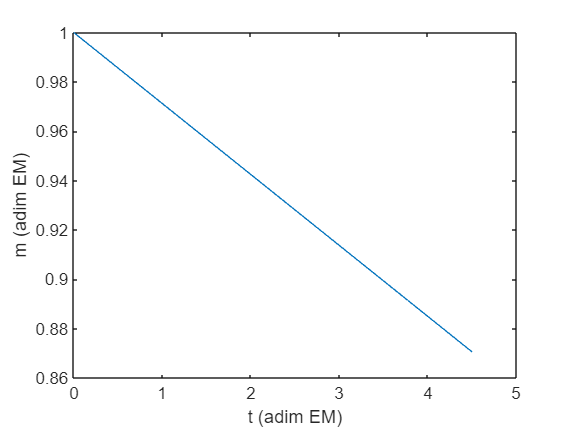

plot(t,estados(:,5))
xlabel("t (adim EM)")
ylabel("m (adim EM)")